# Transient Balance Equations

In engineering, there are 4 common balance equations from conservation principles including mass, momentum, energy, and species. General forms of each equation are shown below with the accumulation term on the left and inlet (in), outlet (out), generation (gen), and consumption (cons) terms on the right side of the equation.


$$\text{Accumulation} = \text{In} - \text{Out} + \text{Generation} - \text{Consumption}$$


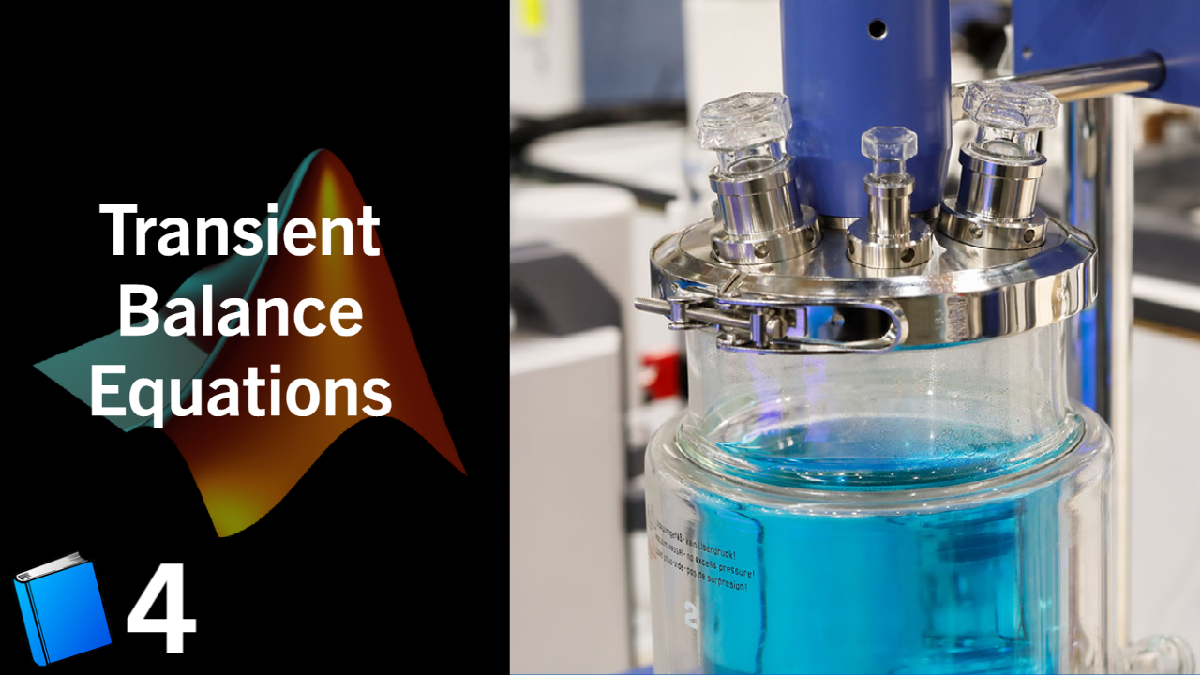

### [View Lecture](https://youtu.be/X5gn9mHfoSQ)

## Mass Balance


$$\frac{dm}{dt}=\frac{d(\rho V)}{dt} = \sum\dot{m}_{in} - \sum\dot{m}_{out}$$


## Species Balance

A species balance tracks the number of moles ($n$) of a species ($A$) in a control volume. The accumulation of $A$, $\frac{d(n_A)}{dt}$, in a control volume is calculated by inlet, outlet, reaction generation, and rection consumption rates.


$$\frac{dn_A}{dt}=\sum\dot{n}_{A_{in}}-\sum\dot{n}_{A_{out}}+\sum\dot{n}_{A_{gen}}-\sum\dot{n}_{A_{cons}}$$


The molar ammount ($n_A$) is often measured as a concentration ($C_A$) and reaction rates are often expressed in terms of a specific reaction rate ($r_A$) as a molar rate of generation per volume.


$$\frac{dc_AV}{dt}=\sum c_{A_{in}}\dot{V}_{in}-\sum c_{A_{out}}\dot{V}_{out} + r_AV$$


## Momentum Balance

A momentum balance is the accumulation of momentum for a control volume equal to the sum of forces ($F$) acting on that control volume.


$$\frac{d(mv)}{dt}=\sum F$$


with $m$ as the mass in the control volume and $v$ as the velocity of the control volume.

## Energy Balance


$$\frac{dE}{dt}=\frac{d(U+K+P)}{dt}=\sum\dot{m}_{in}(\hat{h}_{in} + \frac{v^2_{in}}{2g_c}+\frac{z_{in}g_{in}}{g_c})-\sum\dot{m}_{out}(\hat{h}_{out} + \frac{v^2_{out}}{2g_c}+\frac{z_{out}g_{out}}{g_c})+Q+W_s$$


Kinetic ($K$) and potential ($P$) energy terms are omitted because the internal energy (due to temperature) is typically a much larger contribution than any elevation ($z$) or velocity ($v$) changes of a fluid for most chemical processes.


$$\frac{dh}{dt}=\sum\dot{m}_{in}\hat{h}_{in} - \sum\dot{m}_{out}\hat{h}_{out} +Q +W_s$$


The enthalpy, $h$, is related to the temperature as $m\cdot c_p(T-T_{ref})$ where $c_p$ is the heat cpacity. With a constant reference temperature ($T_{ref}$), this refuces to the following:


$$m\ c_p\frac{dT}{dt} = \sum\dot{m}_{in}c_p(T_{in}-T_{ref}) - \sum\dot{m}_{out}c_p(T_{out}-T_{ref}) + Q + W_s$$


## Exercise:

viewSolution(false)

Use a mass, species, and energy balance to describe the dynamic response in **volume**, **concentration**, and **temperature** of a well-mixed vessel.

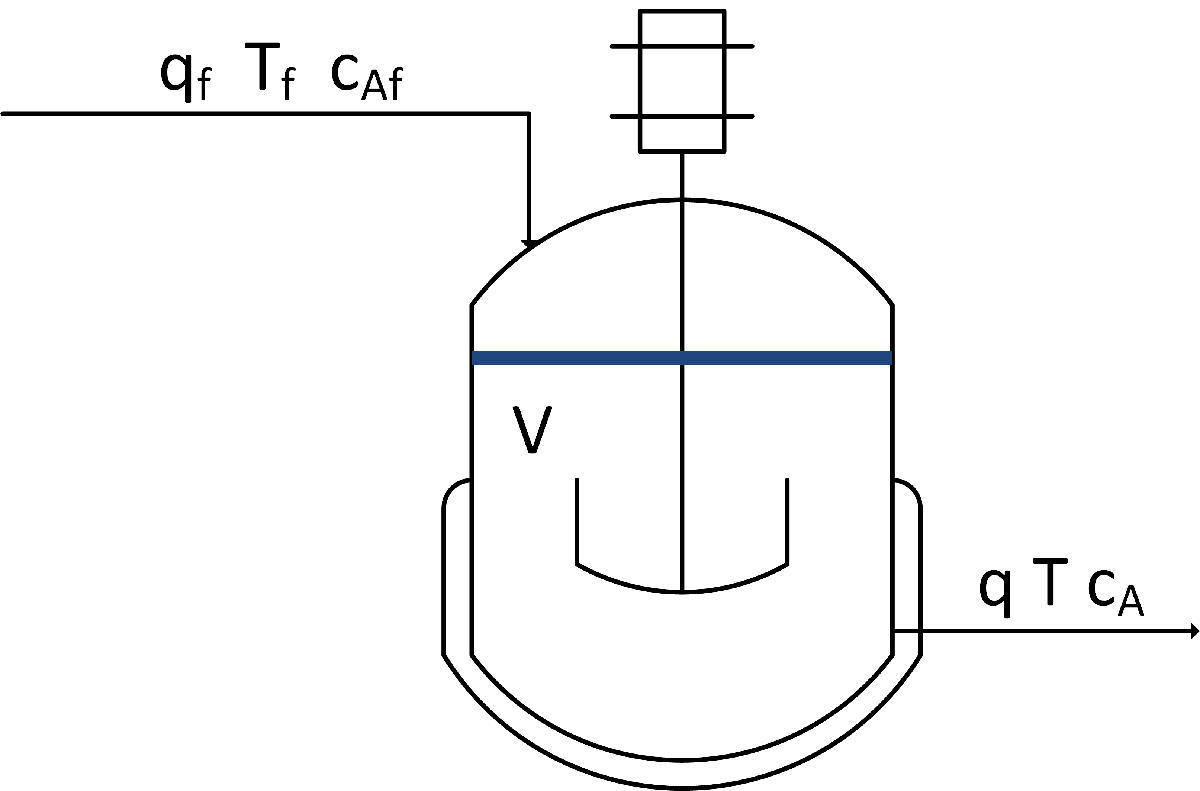

The inlet ($q_f$) and outlet ($q$) volumetric flowrates, feed concentration ($Ca_f$), and inlet temperature ($T_f$) can be adjusted. Initial conditions for the vessel are $V=1.0 \ \text{L}$, $Ca = 0.0 \ \frac{\text{mol}}{\text{L}}$ mol/L, and $T = 350.0 \ \text{K}$. There is no reaction and no significant heat added by the mixer. There is a cooling jacket that can be used to adjust the outlet temperature. Show step changes in the process inputs, and their effect on the volume, concentration, and temperature of the vessel.

% Clear all previous data
clc; clear all; close all;

Initial Conditions

V0 = 1.0;  % L
Ca0 = 0.0;  % Initial Concentration
T0 = 350.0;  % deg K

Time array from 0 to 10 minutes with 101 points

time = linspace(0, 10, 101)

CREATE ARRAYS FOR THE INPUTS(INLET FLOWRATE, OUTLET FLOWRATE, FEED CONCENTRATION AND FEED TEMPERATURE), AND MODIFY THE ARRAYS FOR STEP CHANGES.

Inlet flowrate is given below as an example of how to do this.

% Inlet flowrate (L/min)
qf = ones(length(time), 1) * 5.2;  % Create array with Initial value
qf(50:end) = 5.0;                  % Implement step change at the 50th index (about 5 min)

CREATE ARRAYS TO STORE RESULTS (TANK VOLUME, CONCENTRATION, AND TEMPERATURE)

An array for tank Volume is given below as an example

V = ones(length(time), 1) * V0;


SIMULATE TANK CONDITIONS USING A LOOP THROUGH EACH TIME STEP AND SIMULATING THE CHANGES USING `ode45`

y0 = [V0; Ca0; T0];
for i = 1:(length(time)-1)
    
    
    
    
end

PLOT THE TANK VOLUME, CONCENTRATION, AND TEMPERATURE BELOW

subplot(3,1,1)
plot()
title('Liquid Volume')
ylabel('Volume (L)')
legend({'Volume', 'Feed Flowrate (L/min)'})
subplot(3,1,2)
plot()
ylabel('Concentration (M)')
legend({'Concentration', 'Feed Concentration'})
subplot(3,1,3)
plot()
ylabel('Temperature (K)')
xlabel('Time (min)')
legend({'Temperature', 'Feed Temperature'})

EDIT THE FUNCTION BELOW TO ADD THE MASS BALANCES SO THAT THE FUNCTION SIMULATES CHANGES IN STATES

function [output] = Tank(~, y, q, qf, Caf, Tf)
% Parameters
% y (array): [Volume; Concentration A; Temperature] Terms to be integrated
% q (float): Outlet volumetric flow rate (L/min)
% qf (float): Feed volumetric flow rate (L/min)
% Caf (float): Feed concentration (mol/L)
% Tf (float): Feed temperature (K)
% RESULTS
% dVdt (float): change in Volume (L)
% dCadt (float): change in concentration (mol/L)
% dTdt (float): change in Temperature (K)

% Unpack integrated terms
V = y(1);
Ca = y(2);
T = y(3);

% Reaction
rA = 0.0;  % No reaction

ADD BALANCES BELOW

% Mass balance
dVdt = 0;

% Species Balance
dCadt = 0;

% Energy Balance
dTdt = 0;

LEAVE RESULTS AS FORMATTED

% Note that results must be in a column vector
output = [dVdt; dCadt; dTdt];
end

function viewSolution(view)
if view
disp("% Clear all previous data" + newline + ...
     "clc; clear all; close all;" + newline + ...
     "" + newline + ...
     "% Initial Conditions" + newline + ...
     "V0 = 1.0;  % L" + newline + ...
     "Ca0 = 0.0;  % Initial Concentration" + newline + ...
     "T0 = 350.0;  % deg K" + newline + ...
     "" + newline + ...
     "% time interval (min)" + newline + ...
     "time = linspace(0, 10, 101);" + newline + ...
     "" + newline + ...
     "% Inlet flowrate (L/min)" + newline + ...
     "qf = ones(length(time), 1) * 5.2;" + newline + ...
     "qf(50:end) = 5.1;" + newline + ...
     "" + newline + ...
     "% Outlet Flowrate (L/min)" + newline + ...
     "q = ones(length(time), 1) * 5.0;" + newline + ...
     "" + newline + ...
     "% Feed concentration (mol/L)" + newline + ...
     "Caf = ones(length(time), 1) * 1.0;" + newline + ...
     "Caf(30:end) = 0.5;" + newline + ...
     "" + newline + ...
     "% Feed Temperature (K)" + newline + ...
     "Tf = ones(length(time), 1) * 300.0;" + newline + ...
     "Tf(70:end) = 325.0;" + newline + ...
     "" + newline + ...
     "% Results storage" + newline + ...
     "V = ones(length(time), 1) * V0;" + newline + ...
     "Ca = ones(length(time), 1) * Ca0;" + newline + ...
     "T = ones(length(time), 1) * T0;" + newline + ...
     "" + newline + ...
     "% Loop through time steps" + newline + ...
     "y0 = [V0; Ca0; T0];" + newline + ...
     "for i = 1:(length(time)-1)" + newline + ...
     "    ts = [time(1) time(2)];" + newline + ...
     "    [t, y] = ode45(@(t, y) Tank(t, y, q(i), qf(i), Caf(i), Tf(i)), ts, y0);" + newline + ...
     "    % assign output to storage arrays" + newline + ...
     "    y0 = y(end,:);" + newline + ...
     "    V(i+1) = y0(1);" + newline + ...
     "    Ca(i+1) = y0(2);" + newline + ...
     "    T(i+1) = y0(3);" + newline + ...
     "end" + newline + ...
     "" + newline + ...
     "subplot(3,1,1)" + newline + ...
     "plot(time, [V, qf])" + newline + ...
     "title('Liquid Volume')" + newline + ...
     "ylabel('Volume (L)')" + newline + ...
     "legend({'Volume', 'Feed Flowrate (L/min)'})" + newline + ...
     "subplot(3,1,2)" + newline + ...
     "plot(time,[Ca, Caf])" + newline + ...
     "ylabel('Concentration (M)')" + newline + ...
     "legend({'Concentration', 'Feed Concentration'})" + newline + ...
     "subplot(3,1,3)" + newline + ...
     "plot(time,[T, Tf])" + newline + ...
     "ylabel('Temperature (K)')" + newline + ...
     "xlabel('Time (min)')" + newline + ...
     "legend({'Temperature', 'Feed Temperature'})" + newline + ...
     "" + newline + ...
     "function [output] = Tank(~, y, q, qf, Caf, Tf)" + newline + ...
     "% Parameters" + newline + ...
     "% y (array): [Volume; Concentration A; Temperature] Terms to be integrated" + newline + ...
     "% q (float): Outlet volumetric flow rate (L/min)" + newline + ...
     "% qf (float): Feed volumetric flow rate (L/min)" + newline + ...
     "% Caf (float): Feed concentration (mol/L)" + newline + ...
     "% Tf (float): Feed temperature (K)" + newline + ...
     "% RESULTS" + newline + ...
     "% dVdt (float): change in Volume (L)" + newline + ...
     "% dCadt (float): change in concentration (mol/L)" + newline + ...
     "% dTdt (float): change in Temperature (K)" + newline + ...
     "" + newline + ...
     "% Unpack integrated terms" + newline + ...
     "V = y(1);" + newline + ...
     "Ca = y(2);" + newline + ...
     "T = y(3);" + newline + ...
     "" + newline + ...
     "% Reaction" + newline + ...
     "rA = 0.0;  % No reaction" + newline + ...
     "" + newline + ...
     "% Mass balance" + newline + ...
     "dVdt = qf - q;" + newline + ...
     "" + newline + ...
     "% Species Balance" + newline + ...
     "dCadt = (qf * Caf - q * Ca) / V - rA - (Ca * dVdt / V);" + newline + ...
     "" + newline + ...
     "% Energy Balance" + newline + ...
     "dTdt = (qf*Tf - q*T)/V - (T*dVdt/V);" + newline + ...
     "" + newline + ...
     "% Note that results must be in a coumn vector" + newline + ...
     "output = [dVdt; dCadt; dTdt];" + newline + ...
	 "end")
end
end
